# MTH 4800 Numerical Analysis I Homework 2

## Jarred Maestas

        1. Describe how the Bisection method finds a root, and why it makes sense to have an error bound that divides by two with each iteration.

            - The Bisection method works much like a binary search, systematically finding a root within a given interval $[a, b]$. The method assumes $f(x)$ is continuous on $[a,b]$. By the Intermediate Value Theorem, if $f(a)$ and $f(b)$ have opposite signs, then $f(x) = 0$ has at least one solution in $ [a,b]$. After confirming opposite signs at the endpoints, we evaluate the midpoint $c=\frac{a+b}{2}$. If $f(a)$ and $f(c)$ have opposite signs, the root lies in $[a,c]$; otherwise it lies in $[c,b]$. We replace our interval with whichever half contains the root and repeat this process until the interval width $|b-a|$ is within our defined tolerance, at which point $c$ approximates the root.

            The error bound halves because the interval width halves at each iteration which directly coorelates to the maximum possible error. At iteration $n$, the interval width becomes $\frac{b-a}{2^n}$, and since our approximation is the midpoint of this interval, the maximum distance from the midpoint to the true root is half the interval width, giving us a maximum error of $\frac{b-a}{2^{n+1}}$.

        2. Describe how we use a fixed point to find a root and draw a picture to show what happens for various slopes at/near the fixed point (at least two different scenarios.)

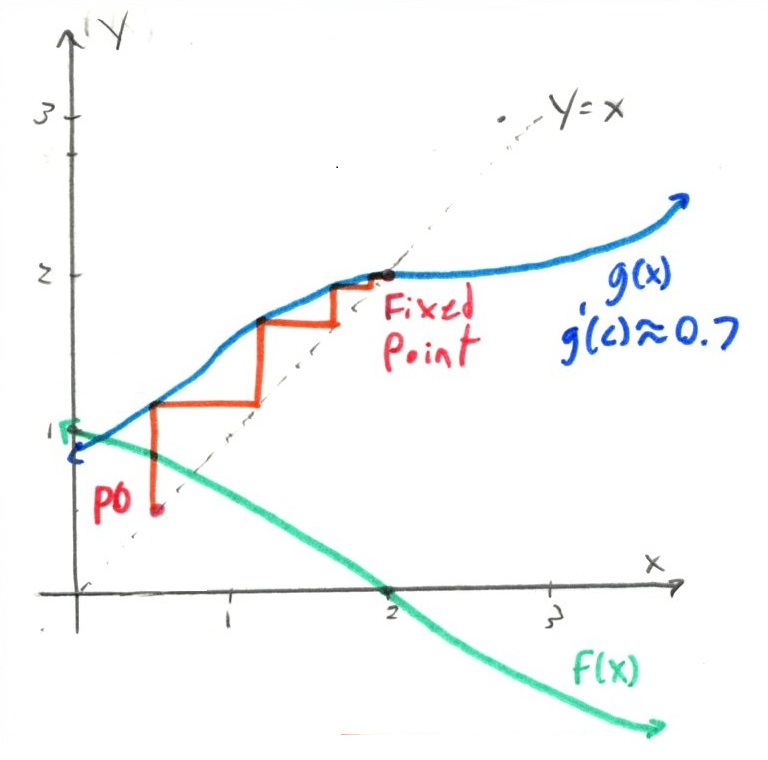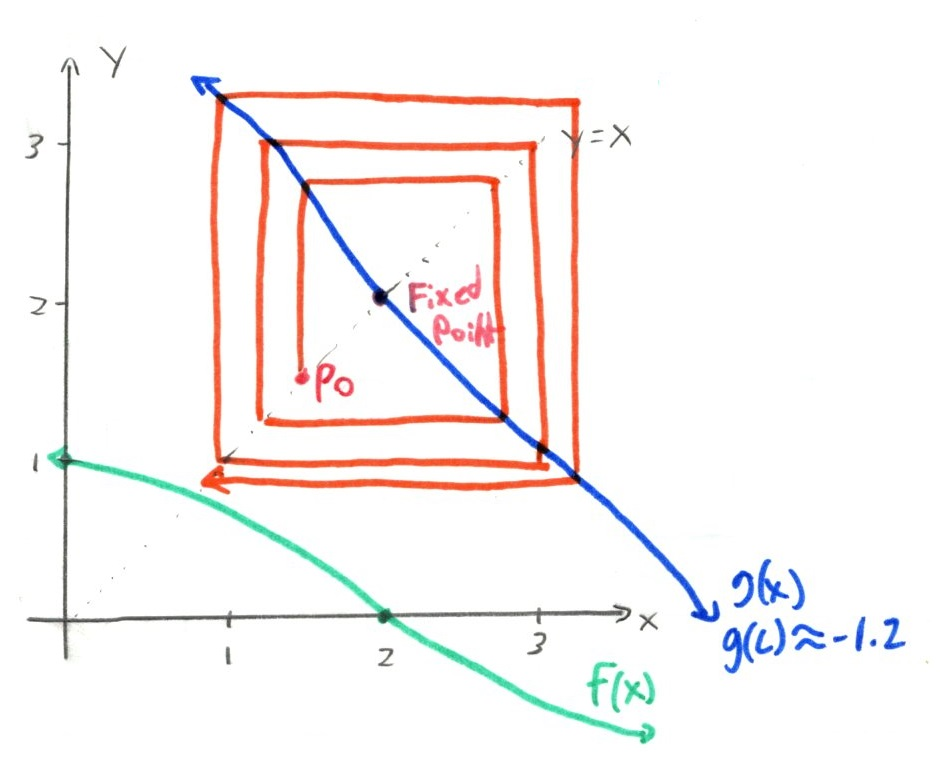

            - The Fixed Point Iteration Method starts with the root finding problem$f(x) = 0 $ and converts it into a fixed point problem by deriving a function $g(x)$ from $f(x)$.This transformation works because if we can find a value where $g(x) = x$ (called a "fixed point"), then that same value will also satisfy $f(x)=0$. A fixed point occurs when $g(x)=x$, which geometrically represents any point where the function $g(x)$ intersects with the line $y = x$.

            Mathematically, we measure this steepness using the derivative $g'(x)$. If the absolute value of this derivative stays smaller than 1 near our solution, then our method will work. If the derivative gets too large ($g'(x) > 1$), the method will fail. The viability of any rearrangement depends on whether $|g'(x)| < 1$ near the solution, which determines if the iterations will converge or diverge. This condition is formally established by the Fixed Point Convergence Theorem. The theorem states that if$ g(x)$ is continuous on an interval $[a,b]$, maps the interval to itself, and satisfies $|g'(x)| \le  \rho  < 1$ for some constant $\rho $, then the iteration $p_n = g(p_{n-1})$ will converge to a unique fixed point for any starting value $p_0$ in the interval. The proof shows that the error decreases by a factor of $\rho $ at each iteration: $|p_n - p| \le  \rho ^n|p_0 - p|$, guaranteeing convergence since $\rho ^n \to  0$ as $n \to  \infty$. 

            The iterative process begins with an initial guess $p_0$ and repeatedly applies$p_n = g(p_{n-1})$ until consecutive approximations are sufficiently close. When the derivative condition $|g'(x)| < 1$ is satisfied, the iterations spiral toward the intersection point of $g(x)$ and $y = x$, which simultaneously solves both the fixed point equation $x = g(x)$ and thus the original root equation $f(x) = 0$.

        3. In what way is the fixed point iteration a family of methods, rather than just one method like bisection?

            - Fixed point iteration represents a "family of methods" because, unlike bisection which follows a single prescribed algorithm, it offers infinite ways to rearrange the same root-finding problem $f(x) = 0$ into different fixed point forms $x = g(x)$. Each rearrangement creates a fundamentally different iterative method with its own convergence properties.

            This concept becomes clear when considering multiple ways to convert $f(x) = 0$ into fixed point problems. For any given equation, you could create any infinite combination of $g(x_i)$, where each choice produces a different iteration function. The 'family' nature of fixed point methods means that from a single equation, you could derive many different iterative approaches where some might converge rapidly, others might converge slowly, and still others might not converge entirtely.

        4. What is the basic condition for convergence of the fixed point iteration, and how does the speed of convergence relate to the derivative of the iteration function g?

            - The basic condition for convergence of fixed point iteration is $|g'(x)| \le  \rho  < 1$ near the fixed point, where $\rho $ is some constant less than 1. This derivative condition ensures that the function $g(x)$ is "slowly varying" meaning each iteration brings you closer to the final answer. The speed of convergence is directly controlled by the magnitude of this derivative bound $\rho $.

            The error decreases by approximately a factor of $\rho $ at each iteration, following the relationship $|p_n - p| \le  \rho ^n|p_0 - p|$, where $p$ is the true fixed point. The magnitude of $\rho $ directly determines the convergence speed such that when $\rho $ is close to zero, the function is nearly flat and convergence is very fast, while values around 0.5 provide moderate convergence speed. As $\rho $ approaches $0.9^-$, convergence becomes slow and requires many iterations to achieve acceptable accuracy. When $\rho $ reaches or exceeds 1, the method fails to converge and instead diverges away from the solution.

            The smaller the derivative magnitude, the faster the convergence rate, which explains why analyzing $g'(x)$ is essential for both predicting performance and choosing among different possible rearrangements of the same root-finding problem.

        5. Apply the bisection method to find the root of the function $f (x) = \sqrt{x} - 1.1$ starting from the interval $ [0, 2] $ (that is, $a = 0$ and $b = 2$), with $atol = 1.e - 8$ (you can use the Matlab code to reach your tolerance, as long as you write out the first two iterations by hand)

% Simple implementation of the bisection root-finding method.
% mybisect(f,a,b,tol) returns c: an approximation to a root of f in [a,b]
% Preconditions: f(a)*f(b) < 0 (there is at least one sign change).

function [c, iter] = mybisect(f, a, b, tol)
   % mybisect - find a root of f on [a,b] using the bisection method
   % Inputs:
   %   f   - function handle, f(x)
   %   a,b - interval endpoints (must satisfy f(a)*f(b) < 0)
   %   tol - tolerance for stopping criterion (half-interval width)
   % Output:
   %   c   - approximate root (midpoint of final interval)
   
   % Evaluate the function at the interval endpoints once.
   fa = f(a); % f at lower bound
   fb = f(b); % f at upper bound

   % Check the necessary condition for bisection: opposite signs at endpoints.
   % If not satisfied, the algorithm cannot guarantee a root in [a,b].
   if sign(fa)*sign(fb) >= 0
       error('f(a)f(b)<0 not satisfied!'); % signal misuse / bad interval
   end

   iter = 1;

   % Main bisection loop:
   % Continue until the half-width of the interval is <= tol.
   % The half-width (b-a)/2 is the maximum possible error of the midpoint.
   while (b - a)/2 > tol
       % Compute midpoint of the current interval
       c = (a+b)/2;
       fc = f(c); % evaluate f at midpoint

       % If fc is exactly zero (rare for floating point), we've found the root.
       if fc == 0
           return;
       end

       % Determine which subinterval contains the sign change:
       % If f(a) and f(c) have opposite signs, root is in [a,c], otherwise in [c,b].
       if sign(fa)*sign(fc) < 0
           % Root lies between a and c: update upper bound to c.
           b = c;
       else
           % Root lies between c and b: update lower bound to c.
           a = c;
           fa = fc; % update cached value for f(a)
       end
       iter = iter + 1; % Increment iteration count
   end

   % When loop ends, return midpoint of final interval as the approximate root.
   c = (a+b)/2;
end

% Test function with roots inside the requested intervals:
% Tolerance requested by the assignment (accuracy within 10^-2)
tol = 1e-8;

% Define the function given in the problem:
f = @(x) sqrt(x) - 1.1;

% Intervals to test (each row is [a b])
intervals = [0, 2;];

% Loop over intervals, call mybisect, and display results
for k = 1:size(intervals,1)
    a = intervals(k,1);
    b = intervals(k,2);
    try
        % mybisect checks that f(a) and f(b) have opposite signs and then bisects
        [root, iter] = mybisect(f, a, b, tol);
        fr = f(root);
        ok = abs(fr) <= tol; % check whether residual meets requested accuracy
        fprintf('Interval [%g, %g], root ≈ %.6f, f(root) = %.2e, |f|<=tol %d, iterations = %d\n',...
            a, b, root, fr, ok, iter);
    catch E
        % If the interval does not bracket a root or another error occurs, print message
        fprintf('Interval [%g, %g]: ERROR - %s\n', a, b, E.message);
    end
end

Interval [0, 2], root ≈ 1.210000, f(root) = 4.06e-10, |f|<=tol 1, iterations = 28


            (a) How many iterations are required? Does the iteration count match the expectations based on our convergence analysis? (Does it converge in the number of iterations expected?)

                - According to the Bisection Method Algorithm there were 28 iterations required. This coincides with the evaluation of the convergence of the Bisection method:


$$n \approx \text{number of iterations}, \epsilon = \text{desired tolerence}, [a, b] = \text{initial search interval}$$



$$n \geq \frac{ln(b-a)-ln(\epsilon)}{ln2}$$



$$n \geq \frac{ln(0-2)-ln(1\times10^-8)}{ln2}=\frac{ln(2)-ln(1\times10^-8)}{ln2}=1-\frac{ln(1\times10^-8)}{ln2}=1+26.575425=27.575425$$


            (b) What was the resulting absolute error? Could this error be predicted by our convergence analysis? If so, how and/or why?

                - The resulting absolute error from the Bisection Method Algorithm was $4.06e-10$. This could be predicted by our convergence analysis because the resulting error is decreased roughly around half for each iteration, thus we can use the iteration count to approximate the absolute error using the following method:


$$\epsilon_n=\frac{b-a}{2^n}=\frac{2-0}{2^{28}}=\frac{28}{2^{28}}=7.5e-9$$


        6. Consider the function $g(x) = x^2 + \frac{3}{16}$

            (a) This function has two fixed points, $g(x) = x$, what are they?

            (b) Consider the fixed point iteration $x_{k+1} = g(x_k)$ for this $g$. For which of the points you found in (a) can you be sure that the iterations will converge to that fixed point? Justify your answer.

            (c) For the point(s) you found in (b), roughly how many iterations will be required to reduce the convergence error by a factor of 10? (1/10th of the current error?)

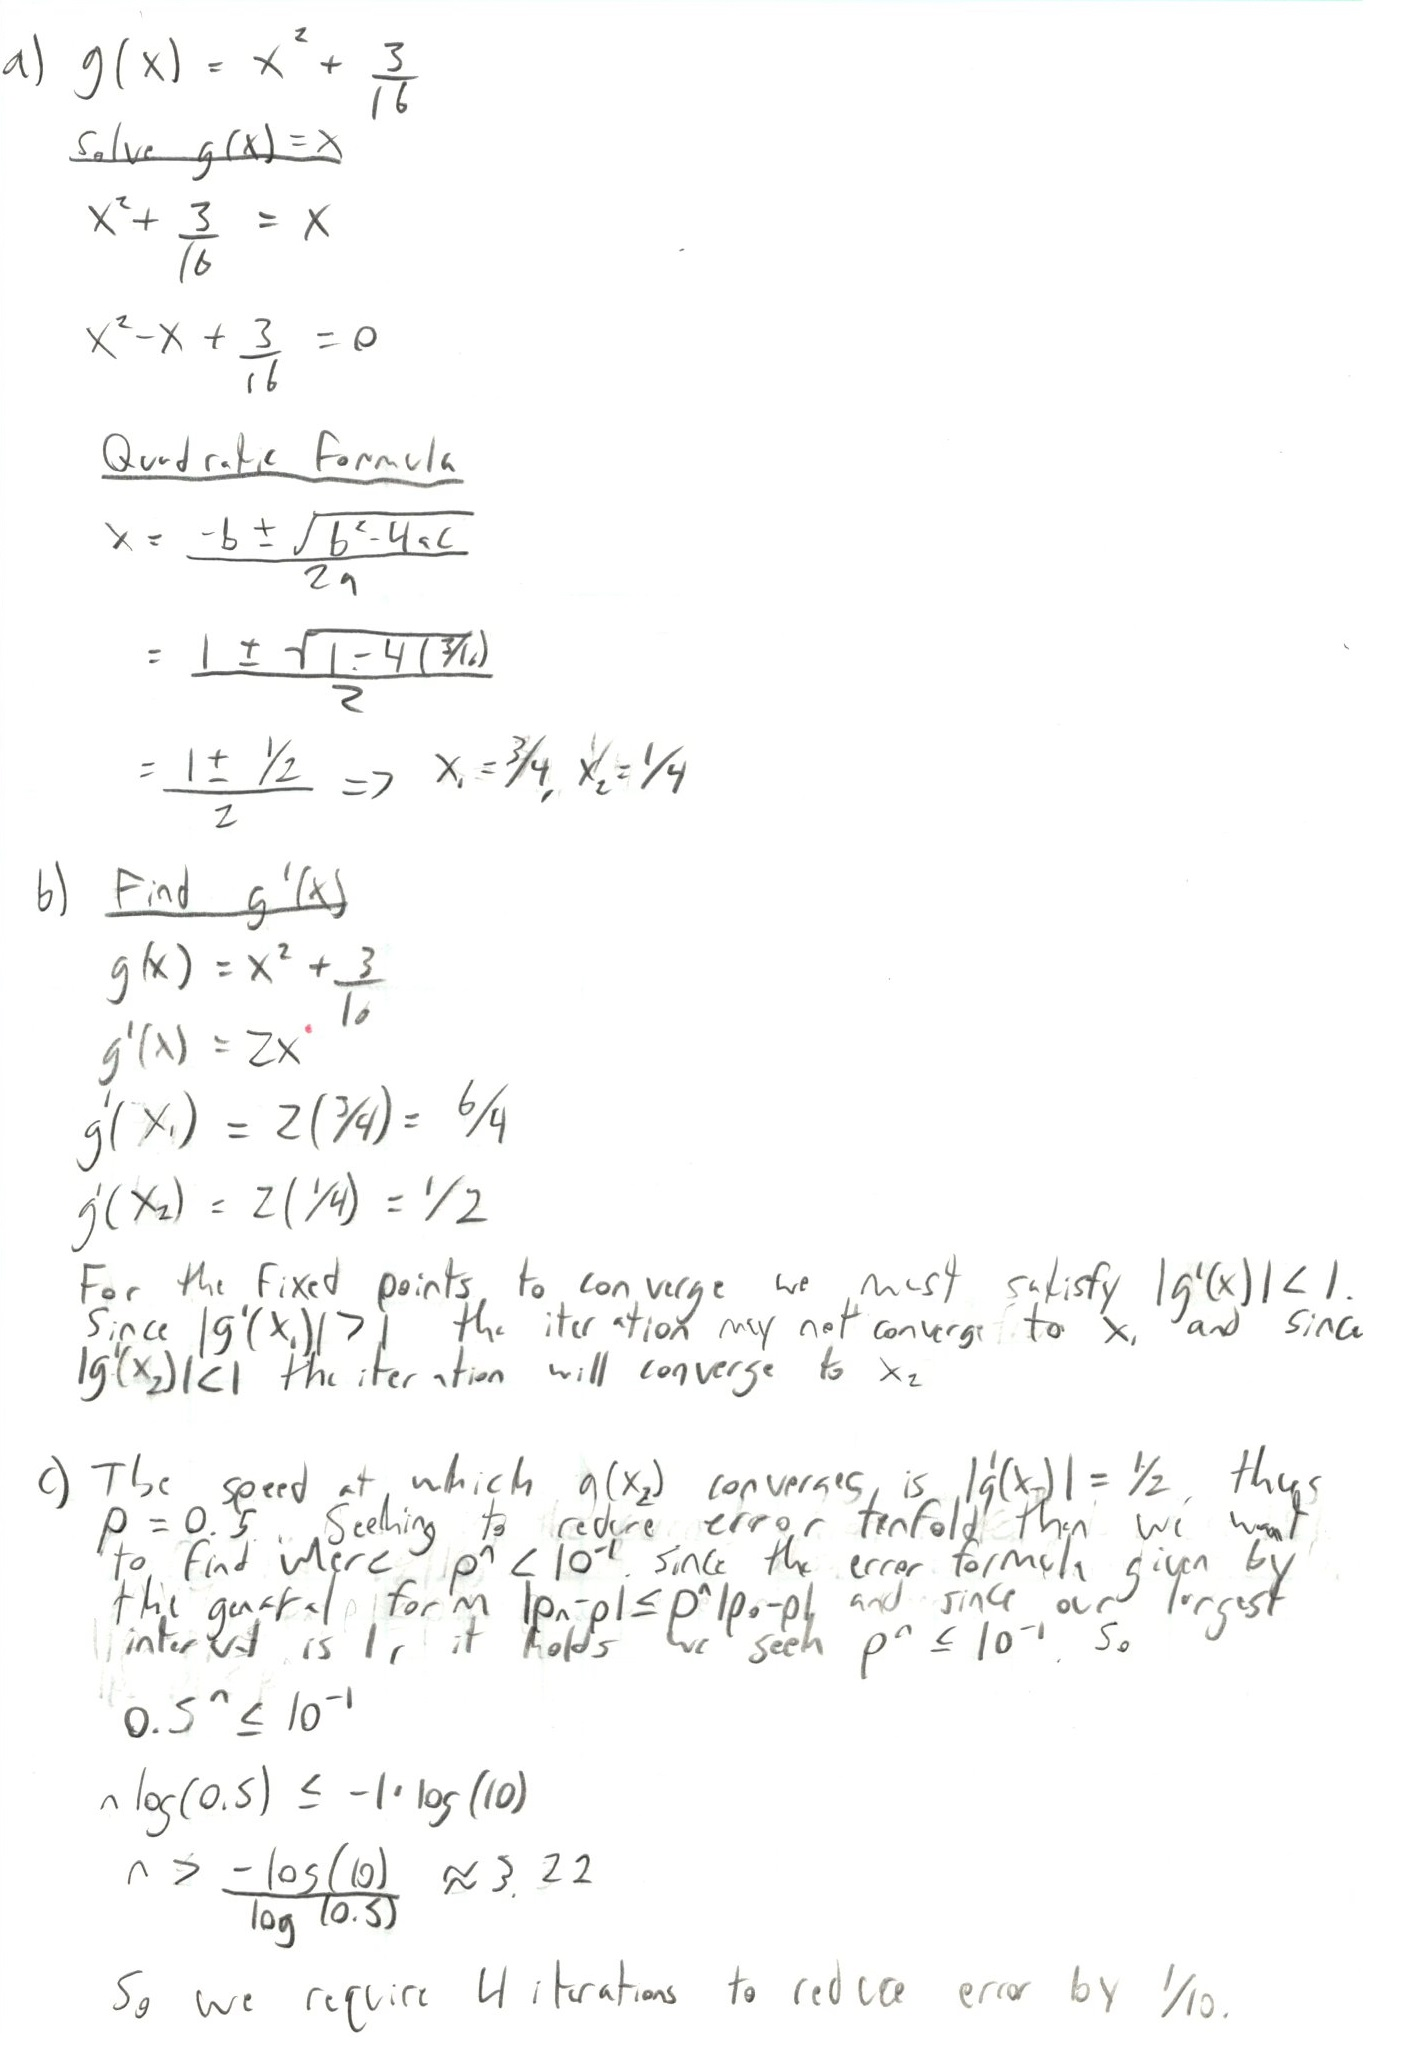

        7. Let $f (x) = x^3 - 2x + 1$, to solve the root finding problem $f (x) = 0$,

- Derive (NO! I do NOT mean differentiate, the terms mean different things) each of the following

- fixed-point functions

- Then determine which, if any, of the functions will converge (which may require differentiation.)

- Explain. Assume $p_0 = \frac{1}{2}$ for each function.

(a) $g(x) = \frac{1}{2}(x^3 + 1)$

(b) $g(x) = \frac{2}{x} - \frac{1}{x^2}$

(c) $g(x) =\sqrt{2 - \frac{1}{x}}$

(d) $g(x) = \sqrt[3]{1-2x}$